clc
clear
freq = 1/333;
m = 0.35;

qualsis_error = 1.0554; %+-mm error


enumerate = @(values) [1:length(values)];

names = ["nosex", "nosey", "nosez", "tailx", "taily", "tailz", "leftx", "lefty", "leftz", "rightx",...
    "righty", "rightz", "midx", "midy", "midz", "gx", "gy", "gz", "ax", "ay", "az"];

file_names = [...
    "1_dynamic_dihedral_s1",...
    "2_dynamic_dihedral_s1",...
    "3_dynamic_dihedral_s1",...
    "1_fixed_dihedral_no_elevator",...
    "2_fixed_dihedral_no_elevator",...
    "1_fixed_dihedral_s2",...
    "2_fixed_dihedral_s2",...
    "4_fixed_dihedral_s2",...
    "2_cf_wing",...
    "3_cf_wing",...
    ];

data = struct;
for i = file_names
    data.("a"+i) = readtable(i+".csv");
    data.("a"+i).Properties.VariableNames = names;
    
    diff_Z = data.("a"+i).tailz - data.("a"+i).midz;
    diff_Y = data.("a"+i).taily - data.("a"+i).midy;
    diff_X = data.("a"+i).tailx - data.("a"+i).midx;
    data.("a"+i).pitch = atand(diff_Z./diff_Y)-7;
    data.("a"+i).yaw = atand(diff_Y./diff_X);
    
    per_error = qualsis_error./diff_Z + qualsis_error./diff_Y;
    abs_error = per_error .* (diff_Z./diff_Y);
    data.("a"+i).pitch_error = abs((atand(diff_Z./diff_Y)-7 + atand(abs_error)) - (atand(diff_Z./diff_Y)-7 - atand(abs_error)));
    
    diff_Z = data.("a"+i).leftz - data.("a"+i).rightz;
    diff_Y = data.("a"+i).lefty - data.("a"+i).righty;
    diff_X = data.("a"+i).leftx - data.("a"+i).rightx;
    data.("a"+i).roll = atand( diff_Z./diff_X);
    
    data.("a"+i).t = (freq:freq:(freq)*length(data.("a"+i).gy))';
    
    data.("a"+i).vx = [0; diff(0.5 * (data.("a"+i).midx + data.("a"+i).tailx)) ./ diff(data.("a"+i).t) * 1e-3];
    data.("a"+i).vy = [0; diff(0.5 * (data.("a"+i).midy + data.("a"+i).taily)) ./ diff(data.("a"+i).t) * 1e-3];
    data.("a"+i).vz = [0; diff(0.5 * (data.("a"+i).midz + data.("a"+i).tailz)) ./ diff(data.("a"+i).t) * 1e-3];
    data.("a"+i).v = vecnorm([data.("a"+i).vx, data.("a"+i).vy, data.("a"+i).vz]')';

    data.("a"+i).glide_angle = smooth(atand(data.("a"+i).vz./data.("a"+i).vy),40, 'sgolay');
    data.("a"+i).AoA = data.("a"+i).pitch - data.("a"+i).glide_angle;

    error_one = 0.5*(qualsis_error + qualsis_error) + 0.5*(qualsis_error + qualsis_error);
    error_vx = error_one./data.("a"+i).vx;
    error_vy = error_one./data.("a"+i).vy;
    error_vz = abs(error_one./data.("a"+i).vz);
    error_v = error_one./data.("a"+i).v;
    data.("a"+i).glide_angle_error = atand( (data.("a"+i).vz./data.("a"+i).vy) + (error_v).*(data.("a"+i).vz./data.("a"+i).vy)) - atand( (data.("a"+i).vz./data.("a"+i).vy) - (error_v).*(data.("a"+i).vz./data.("a"+i).vy));

%     data.("a"+i).a_x = ( data.("a"+i).az .* cosd(data.("a"+i).glide_angle) + data.("a"+i).ay) ./ (cosd(data.("a"+i).glide_angle) .* cosd(data.("a"+i).glide_angle) - sind(data.("a"+i).glide_angle));
%     data.("a"+i).a_y = ( data.("a"+i).ay + data.("a"+i).a_x .* sind(data.("a"+i).glide_angle) )./cosd(data.("a"+i).glide_angle);
    
    ga = data.("a"+i).glide_angle;
    d = data.("a"+i);
    % az in lift direction, ay in drag direction
    data.("a"+i).a_d = (d.ay + (d.az - d.ay.*sind(ga))./cosd(ga))./cosd(ga);
    data.("a"+i).a_l = (d.az - data.("a"+i).a_d.*sind(ga))./cosd(ga);
    
    
    data.("a"+i).lift = smooth(data.("a"+i).t, data.("a"+i).a_l, 20, 'sgolay')*m;
    data.("a"+i).drag = smooth(data.("a"+i).t, data.("a"+i).a_d, 20, 'sgolay')*m;
end

%cut off data at impact point
c = data.("a"+file_names(1));
data.("a"+file_names(1)) = c(data.("a"+file_names(1)).t < 1.4, :);
c = data.("a"+file_names(2));
data.("a"+file_names(2)) = c(data.("a"+file_names(2)).t < 1.4, :);
c = data.("a"+file_names(3));
data.("a"+file_names(3)) = c(data.("a"+file_names(3)).t < 1.4, :);

c = data.("a"+file_names(4));
data.("a"+file_names(4)) = c(data.("a"+file_names(4)).t < 0.92, :);
c = data.("a"+file_names(5));
data.("a"+file_names(5)) = c(data.("a"+file_names(5)).t < 0.92, :);

c = data.("a"+file_names(6));
data.("a"+file_names(6)) = c(data.("a"+file_names(6)).t < 1.15, :);
c = data.("a"+file_names(7));
data.("a"+file_names(7)) = c(data.("a"+file_names(7)).t < 1.15, :);
c = data.("a"+file_names(8));
data.("a"+file_names(8)) = c(data.("a"+file_names(8)).t < 1.15, :);

c = data.("a"+file_names(9));
data.("a"+file_names(9)) = c(data.("a"+file_names(9)).t < 0.81, :);
c = data.("a"+file_names(10));
data.("a"+file_names(10)) = c(data.("a"+file_names(10)).t < 0.81, :);


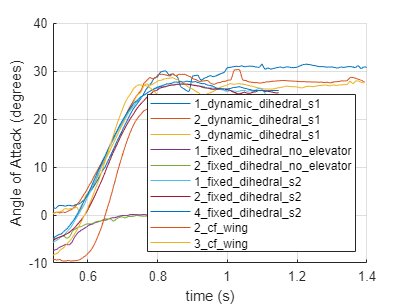

clf
hold on
for i = file_names
    d = data.("a"+i);
    plot(d.t, d.AoA, 'DisplayName',i);
end
hold off
leg = legend();
set(leg,'Interpreter', 'none', 'Location', 'SouthEast')
xlim([0.5,1.4])
grid("on")
xlabel("time (s)")
ylabel("Angle of Attack (degrees)")

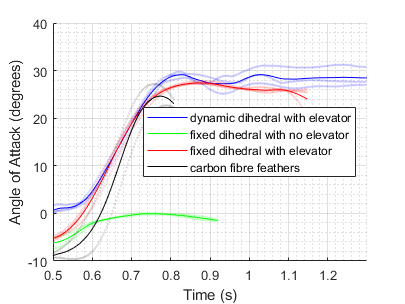

clf
hold on

store_v = [];
index = 1;
for i = 1:3
    d = data.("a"+file_names(i));
    v_smooth = smooth(d.AoA, 40, 'sgolay');
    scatter(d.t, v_smooth,2, "blue", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = v_smooth;
    index = index + 1;
end
plot(d.t, mean(store_v,2), "blue", 'DisplayName',"dynamic dihedral with elevator");

store_v = [];
index = 1;
for i = 4:5
    d = data.("a"+file_names(i));
    v_smooth = smooth(d.AoA, 40, 'sgolay');
    scatter(d.t, v_smooth,2, "green", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = v_smooth;
    index = index + 1;
end
plot(d.t, mean(store_v,2),"green", 'DisplayName',"fixed dihedral with no elevator");


store_v = [];
index = 1;
for i = 6:8
    d = data.("a"+file_names(i));
    v_smooth = smooth(d.AoA, 40, 'sgolay');
    scatter(d.t, v_smooth,2, "red", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = v_smooth;
    index = index + 1;
end
plot(d.t, mean(store_v,2),"red", 'DisplayName',"fixed dihedral with elevator");

store_v = [];
index = 1;
for i = 9:10
    d = data.("a"+file_names(i));
    v_smooth = smooth(d.AoA, 40, 'sgolay');
    scatter(d.t, v_smooth,2, "black", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = v_smooth;
    index = index + 1;
end
plot(d.t, mean(store_v,2),"black", 'DisplayName',"carbon fibre feathers");


hold off
leg = legend();
set(leg,'Interpreter', 'none', 'Location', 'East')
xlim([0.5,1.3])
ylim([-10,40])
xlabel("Time (s)")
ylabel("Angle of Attack (degrees)")

grid
set(gca,'gridlinestyle','-')
grid minor

exportgraphics(gcf,'figures/AoA_configuation_difference.png')

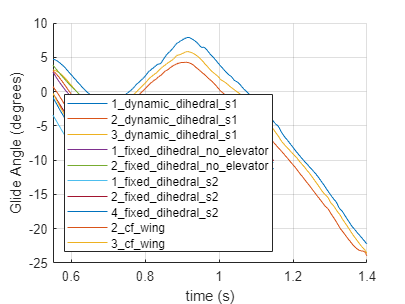

clf
hold on
for i = file_names
    d = data.("a"+i);
    plot(d.t, d.glide_angle, 'DisplayName', i)
end
hold off
leg = legend;
set(leg,'Interpreter', 'none', 'Location', 'SouthWest')
xlim([0.55,1.4])
grid("on")
xlabel("time (s)")
ylabel("Glide Angle (degrees)")

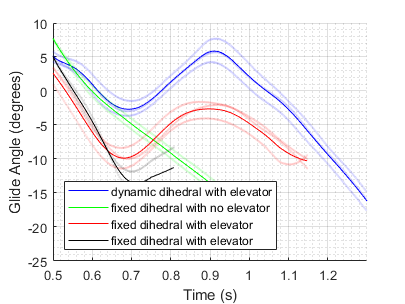

clf
hold on

store_v = [];
index = 1;
for i = 1:3
    d = data.("a"+file_names(i));
    v_smooth = smooth(d.glide_angle, 40, 'sgolay');
    scatter(d.t, v_smooth,2, "blue", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = v_smooth;
    index = index + 1;
end
plot(d.t, mean(store_v,2), "blue", 'DisplayName',"dynamic dihedral with elevator");

store_v = [];
index = 1;
for i = 4:5
    d = data.("a"+file_names(i));
    v_smooth = smooth(d.glide_angle, 40, 'sgolay');
    scatter(d.t, v_smooth,2, "green", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = v_smooth;
    index = index + 1;
end
plot(d.t, mean(store_v,2),"green", 'DisplayName',"fixed dihedral with no elevator");


store_v = [];
index = 1;
for i = 6:8
    d = data.("a"+file_names(i));
    v_smooth = smooth(d.glide_angle, 40, 'sgolay');
    scatter(d.t, v_smooth,2, "red", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = v_smooth;
    index = index + 1;
end
plot(d.t, mean(store_v,2),"red", 'DisplayName',"fixed dihedral with elevator");

store_v = [];
index = 1;
for i = 9:10
    d = data.("a"+file_names(i));
    v_smooth = smooth(d.glide_angle, 40, 'sgolay');
    scatter(d.t, v_smooth,2, "black", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = v_smooth;
    index = index + 1;
end
plot(d.t, mean(store_v,2),"black", 'DisplayName',"fixed dihedral with elevator");


hold off
leg = legend();
set(leg,'Interpreter', 'none', 'Location', 'SouthWest')
xlim([0.5,1.3])
ylim([-25,10])
xlabel("Time (s)")
ylabel("Glide Angle (degrees)")


grid
set(gca,'gridlinestyle','-')
grid minor

exportgraphics(gcf,'figures/glide_angle_configuation_difference.png')

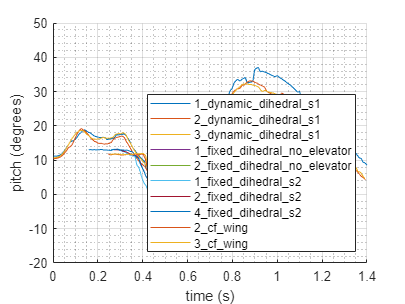

clf
hold on
for i = file_names
    d = data.("a"+i);
    plot(d.t, d.pitch, 'DisplayName',i);
    %plot(d.t, d.AoA, 'DisplayName', "Glide Angle "+i)
end
hold off
leg = legend;
set(leg,'Interpreter', 'none', 'Location', 'SouthEast')
ylim([-20,50])
xlim([0,1.4])
grid("on")
grid("minor")
ylabel("pitch (degrees)")
xlabel("time (s)")

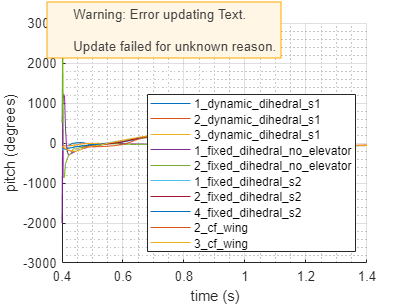

clf
hold on
for i = file_names
    d = data.("a"+i);
    p = smooth(d.pitch,40, 'sgolay');
    plot(d.t(2:end), diff(p)./diff(d.t), 'DisplayName',i);
    %plot(d.t, d.AoA, 'DisplayName', "Glide Angle "+i)
end
hold off
leg = legend;
set(leg,'Interpreter', 'none', 'Location', 'SouthEast')
xlim([0.4,1.4])
grid("on")
grid("minor")
ylabel("pitch (degrees)")
xlabel("time (s)")

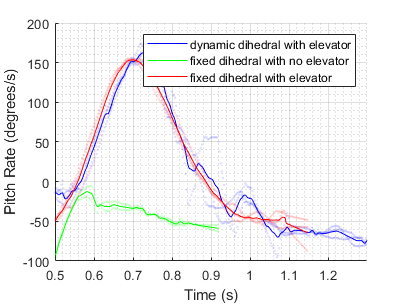

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.



clf
hold on

store_v = [];
index = 1;
for i = 1:3
    d = data.("a"+file_names(i));
    p = smooth(d.pitch,40, 'sgolay');
    scatter(d.t(2:end), diff(p)./diff(d.t),2, "blue", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = diff(p)./diff(d.t);
    index = index + 1;
end
plot(d.t(2:end), mean(store_v,2), "blue", 'DisplayName',"dynamic dihedral with elevator");

store_v = [];
index = 1;
for i = 4:5
    d = data.("a"+file_names(i));
     p = smooth(d.pitch,40, 'sgolay');
    scatter(d.t(2:end), diff(p)./diff(d.t),2, "green", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = diff(p)./diff(d.t);
    index = index + 1;
end
plot(d.t(2:end), mean(store_v,2),"green", 'DisplayName',"fixed dihedral with no elevator");


store_v = [];
index = 1;
for i = 6:8
    d = data.("a"+file_names(i));
     p = smooth(d.pitch,40, 'sgolay');
    scatter(d.t(2:end), diff(p)./diff(d.t),2, "red", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = diff(p)./diff(d.t);
    index = index + 1;
end
plot(d.t(2:end), mean(store_v,2),"red", 'DisplayName',"fixed dihedral with elevator");


hold off
leg = legend();
set(leg,'Interpreter', 'none', 'Location', 'NorthEast')
xlim([0.5,1.3])
xlabel("Time (s)")
ylabel("Pitch Rate (degrees/s)")

grid
set(gca,'gridlinestyle','-')
grid minor


exportgraphics(gcf,'figures/pitch_rate_configuation_difference.png')

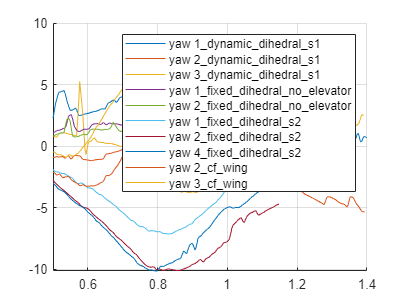

clf
hold on
for i = file_names
    d = data.("a"+i);
    rm = rmmissing(d.yaw);
    plot(d.t, abs(d.yaw)+ rm(1), 'DisplayName', "yaw "+i)
end
hold off
legend
xlim([0.5,1.4])
grid("on")
leg = legend;
set(leg,'Interpreter', 'none')

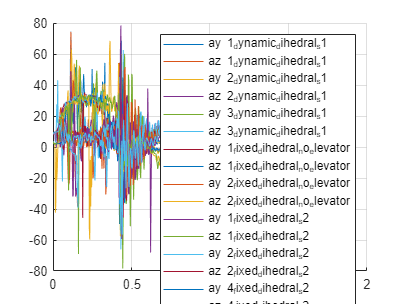

clf
hold on
for i = file_names
    d = data.("a"+i);
%     plot(d.t, d.ax, 'DisplayName',"ax "+i);
    plot(d.t, d.ay, 'DisplayName', "ay "+i)
    plot(d.t, d.az, 'DisplayName', "az "+i)
end
hold off
legend
xlim([0,2])
grid("on")

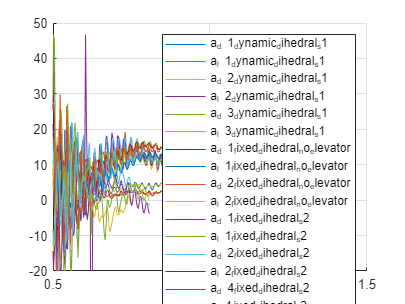

clf
hold on
for i = file_names
    d = data.("a"+i);
    plot(d.t, d.a_d, 'DisplayName',"a_d "+i);
    plot(d.t, d.a_l, 'DisplayName', "a_l "+i)
end
hold off
legend
ylim([-20,50])
xlim([0.5,1.5])
grid("on")

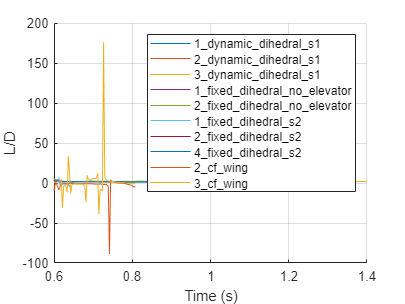

clf
hold on
for i = file_names
    d = data.("a"+i);
%     plot(d.t, d.drag, 'DisplayName',"drag "+i);
%     plot(d.t, d.lift, 'DisplayName',"lift "+i);
    plot(d.t, d.lift./d.drag, 'DisplayName', i)
end
hold off
legend
xlim([0.6,1.4])
xlabel("Time (s)")
ylabel("L/D")
grid("on")
leg = legend();
set(leg,'Interpreter', 'none', 'Location', 'NorthEast')

% clf
% storedrag = [];
% storelift = [];
% storeaoa = [];
% 
% hold on
% 
% for i = file_names
%     yyaxis left
%     d = data.("a"+i);
%     d = d(d.t>0.6, :);
%     d = d(d.t<1.4, :);
%     
%     plot(d.t, mean(-d.drag,2), 'DisplayName',"drag");
%     plot(d.t, mean(d.lift,2), 'DisplayName',"lift");
%     ylabel("Force (N)")
%     yyaxis right
%     ylabel("AoA")
%     plot(d.t, mean(d.AoA,2), "HandleVisibility","off");
% end
% hold off
% legend
% xlabel("Time (s)")
% grid("on")

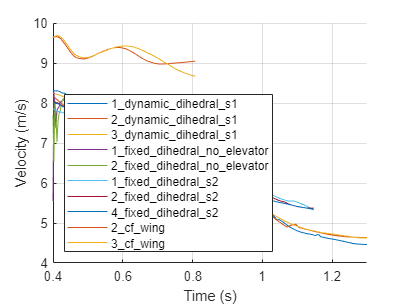

clf
hold on
for i = file_names
    d = data.("a"+i);
    v_smooth = smooth(d.v,40, 'sgolay');
    plot(d.t, v_smooth,'DisplayName',""+i);
end
hold off
leg = legend();
set(leg,'Interpreter', 'none', 'Location', 'SouthWest')
xlim([0.4,1.3])
xlabel("Time (s)")
ylabel("Velocity (m/s)")
grid("on")

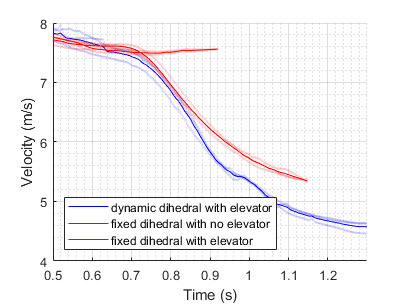

clf
hold on

store_v = [];
index = 1;
for i = 1:3
    d = data.("a"+file_names(i));
    v_smooth = smooth(d.v,40, 'sgolay');
    scatter(d.t, v_smooth,2, "blue", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = v_smooth;
    index = index + 1;
end
plot(d.t, mean(store_v,2), "blue", 'DisplayName',"dynamic dihedral with elevator");

store_v = [];
index = 1;
for i = 4:5
    d = data.("a"+file_names(i));
    v_smooth = smooth(d.v,40, 'sgolay');
    scatter(d.t, v_smooth,2, "red", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = v_smooth;
    index = index + 1;
end
plot(d.t, mean(store_v,2),"red", 'DisplayName',"fixed dihedral with no elevator");

store_v = [];
index = 1;
for i = 6:8
    d = data.("a"+file_names(i));
    v_smooth = smooth(d.v,40, 'sgolay');
    scatter(d.t, v_smooth,2, "red", "HandleVisibility","off","MarkerEdgeAlpha",0.1);
    store_v(:,index) = v_smooth;
    index = index + 1;
end
plot(d.t, mean(store_v,2),"red", 'DisplayName',"fixed dihedral with elevator");


hold off
leg = legend();
set(leg,'Interpreter', 'none', 'Location', 'SouthWest')
xlim([0.5,1.3])
xlabel("Time (s)")
ylabel("Velocity (m/s)")

grid
set(gca,'gridlinestyle','-')
grid minor

exportgraphics(gcf,'figures/v_configuation_difference.png') 

clf
hold on


index = 1;
i = 9

i = 9

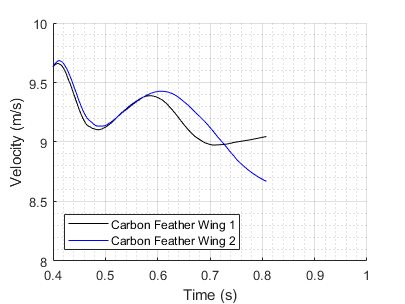

d = data.("a"+file_names(i));
v_smooth = smooth(d.v,40, 'sgolay');
plot(d.t, v_smooth, "black", 'DisplayName','Carbon Feather Wing 1');

i=10;
%plot(d.t, mean(store_v,2), "black", 'DisplayName',"dynamic dihedral with elevator");
d = data.("a"+file_names(i));
v_smooth = smooth(d.v,40, 'sgolay');
plot(d.t, v_smooth, "blue", 'DisplayName','Carbon Feather Wing 2');


hold off
leg = legend();
set(leg,'Interpreter', 'none', 'Location', 'SouthWest')
xlim([0.4,1])
xlabel("Time (s)")
ylabel("Velocity (m/s)")
ylim([8,10])

grid
set(gca,'gridlinestyle','-')
grid minor

exportgraphics(gcf,'figures/v_cf_configuation.png') 

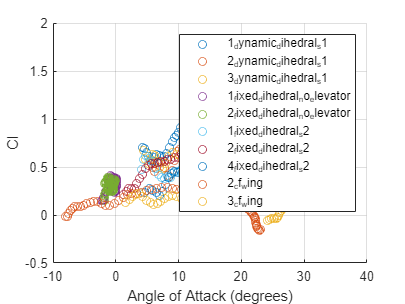

clf
hold on
A = 0.15*0.8;
store = [];
for i = file_names
    d = data.("a"+i);
    d = d(d.t>0.6, :);
    d = d(d.t<1.3, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    scatter(d.AoA, Cl, 'DisplayName',""+i)
end
hold off
legend
xlabel("Angle of Attack (degrees)")
ylabel("Cl")
grid("on")

### Dynamic dihedral

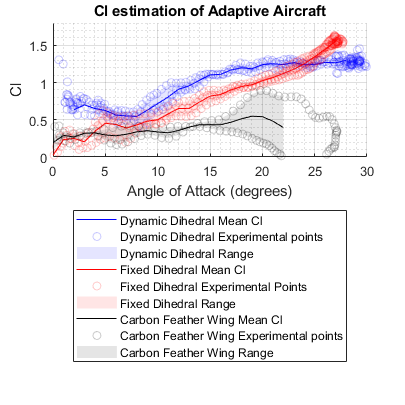

file_names = [...
    "1_dynamic_dihedral_s1",...
    "2_dynamic_dihedral_s1",...
    "3_dynamic_dihedral_s1",...
    "1_fixed_dihedral_s2",...
    "2_fixed_dihedral_s2",...
    "4_fixed_dihedral_s2",...
    "2_cf_wing",...
    "3_cf_wing"
    ];

clf
A = 0.15*0.8;
min_r = 0;
max_r = 30;
storecl = [];
storeaoa = [];
hold("on")
enumerate = @(values) [1:length(values)];
for i = enumerate(file_names(1:3))
    d = data.("a"+file_names(i));
    d = d(d.t>0.55, :);
    d = d(d.t<0.85, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    ClInterp = interp1(d.AoA, Cl, min_r:max_r);
    storecl(:, i) = ClInterp;
    storeaoa(:, i) = min_r:max_r;
    scatter(d.AoA, Cl, "blue","MarkerEdgeAlpha",0.2, 'HandleVisibility',"off");
end

plot(min_r:max_r, mean(storecl,2), "blue")
%dummy scatter for legend
scatter(d.AoA-100, Cl-100, "blue","MarkerEdgeAlpha",0.2);

high =  max(storecl,[],2);
low = min(storecl,[],2);
x = (min_r:max_r)';
high = high(5:30);
low = low(5:30);
x = x(5:30);
patchx = [x; x(end:-1:1)];
patchy = [low; high(end:-1:1)];
P1 = patch(patchx, patchy, 'r');
set(P1, 'facecolor', "blue", 'edgecolor', 'none');
set(P1, 'facealpha', 0.1);


storecl = [];
storeaoa = [];

for i = enumerate(file_names(4:6))
    i = i + 3;
    d = data.("a"+file_names(i));
    d = d(d.t>0.45, :);
    d = d(d.t<0.86, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    ClInterp = interp1(d.AoA, Cl, min_r:max_r);
    storecl(:, i - 3) = ClInterp;
    storeaoa(:, i - 3) = min_r:max_r;
    scatter(d.AoA, Cl, "red","MarkerEdgeAlpha",0.2, 'HandleVisibility',"off");
end

plot(min_r:max_r, mean(storecl,2), "red")
%dummy scatter for legend
scatter(d.AoA-100, Cl-100, "red","MarkerEdgeAlpha",0.2);


high =  max(storecl,[],2);
low = min(storecl,[],2);
x = (min_r:max_r)';
high = high(5:27);
low = low(5:27);
x = x(5:27);
patchx = [x; x(end:-1:1)];
patchy = [low; high(end:-1:1)];
P1 = patch(patchx, patchy, 'r');
set(P1, 'facecolor', "red", 'edgecolor', 'none');
set(P1, 'facealpha', 0.1);
% 
% high =  mean(storecl,2) + std(storecl,[],2);
% low = mean(storecl,2) - std(storecl,[],2);
% x = (min_r:max_r)';
% patchx = [x; x(end:-1:1)];
% patchy = [low; high(end:-1:1)];
% P2 = patch(patchx, patchy, 'r');
% set(P2, 'facecolor', "yellow", 'edgecolor', 'none');
% set(P2, 'facealpha', 0.2);

storecl = [];
storeaoa = [];

for i = enumerate(file_names(7:8))
    i = i + 6;
    d = data.("a"+file_names(i));
    d = d(d.t>0.4, :);
    d = d(d.t<0.79, :);
    Cl = (2 .* (d.lift./0.35).*0.45) ./ (1.225 .* d.v.^2 .*(0.15*0.7));
    ClInterp = interp1(d.AoA, Cl, min_r:max_r);
    storecl(:, i - 6) = ClInterp;
    storeaoa(:, i - 6) = min_r:max_r;
    scatter(d.AoA, Cl, "black","MarkerEdgeAlpha",0.2, 'HandleVisibility',"off");
end

plot(min_r:max_r, mean(storecl,2), "black")
%dummy scatter for legend
scatter(d.AoA-100, Cl-100, "black","MarkerEdgeAlpha",0.2);

high =  max(storecl,[],2);
low = min(storecl,[],2);
x = (min_r:max_r)';
high = high(1:23);
low = low(1:23);
x = x(1:23);
patchx = [x; x(end:-1:1)];
patchy = [low; high(end:-1:1)];
P1 = patch(patchx, patchy, 'r');
set(P1, 'facecolor', "black", 'edgecolor', 'none');
set(P1, 'facealpha', 0.1);


hold("off")
xlabel("Angle of Attack (degrees)")
ylabel("Cl")
xlim([min_r,max_r])
ylim([0,1.8])
legend("Dynamic Dihedral Mean Cl", "Dynamic Dihedral Experimental points", "Dynamic Dihedral Range", ...
    "Fixed Dihedral Mean Cl", "Fixed Dihedral Experimental Points", "Fixed Dihedral Range", ...
    "Carbon Feather Wing Mean Cl", "Carbon Feather Wing Experimental points", "Carbon Feather Wing Range", ...
    "Location","southoutside")
title("Cl estimation of Adaptive Aircraft")

grid
set(gca,'gridlinestyle','-')
grid minor

set(gcf,'position',[0,0,700,700])

exportgraphics(gcf,'figures/cl_estimation_comparison.png')


clf
set(gcf, 'position', [680   558   560   420])

file_names = [...
    "1_dynamic_dihedral_s1",...
    "2_dynamic_dihedral_s1",...
    "3_dynamic_dihedral_s1",...
    ];

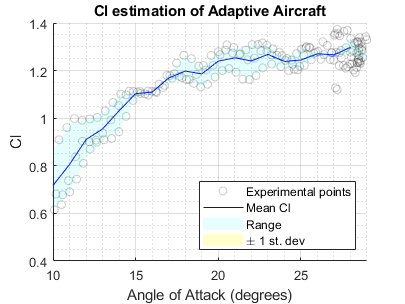

clf
A = 0.15*0.8;
min_r = 10;
max_r = 29;
storecl = [];
storeaoa = [];
hold("on")
enumerate = @(values) [1:length(values)];
for i = enumerate(file_names)
    d = data.("a"+file_names(i));
    d = d(d.t>0.62, :);
    d = d(d.t<0.85, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    ClInterp = interp1(d.AoA, Cl, min_r:max_r);
    storecl(:, i) = ClInterp;
    storeaoa(:, i) = min_r:max_r;
    scatter(d.AoA, Cl, "black","MarkerEdgeAlpha",0.2, 'HandleVisibility',"off");
end

%dummy scatter for legend
scatter(d.AoA-100, Cl-100, "black","MarkerEdgeAlpha",0.2);

plot(min_r:max_r, mean(storecl,2), "blue")

high =  max(storecl,[],2);
low = min(storecl,[],2);
x = (min_r:max_r)';
patchx = [x; x(end:-1:1)];
patchy = [low; high(end:-1:1)];
P1 = patch(patchx, patchy, 'r');
set(P1, 'facecolor', "cyan", 'edgecolor', 'none');
set(P1, 'facealpha', 0.1);

high =  mean(storecl,2) + std(storecl,[],2);
low = mean(storecl,2) - std(storecl,[],2);
x = (min_r:max_r)';
patchx = [x; x(end:-1:1)];
patchy = [low; high(end:-1:1)];
P2 = patch(patchx, patchy, 'r');
set(P2, 'facecolor', "yellow", 'edgecolor', 'none');
set(P2, 'facealpha', 0.2);

hold("off")
xlabel("Angle of Attack (degrees)")
ylabel("Cl")
grid
set(gca,'gridlinestyle','-')
grid minor
xlim([min_r,max_r])
legend("Experimental points", "Mean Cl", "Range","\pm 1 st. dev", "Location","southeast")
title("Cl estimation of Adaptive Aircraft")

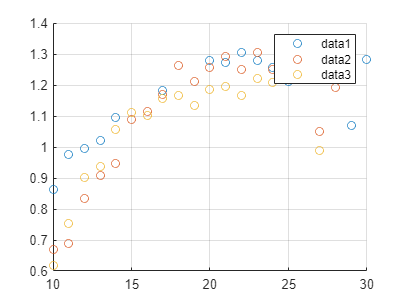

clf
A = 0.15*0.8;
min_r = 10;
max_r = 34;
storecl = [];
storeaoa = [];
hold("on")
enumerate = @(values) [1:length(values)];
for i = enumerate(file_names)
    d = data.("a"+file_names(i));
    d = d(d.t>0.62, :);
    d = d(d.t<1, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    ClInterp = interp1(d.AoA, Cl, min_r:max_r);
    scatter(min_r:max_r, ClInterp);
end
hold("off")
legend
grid on

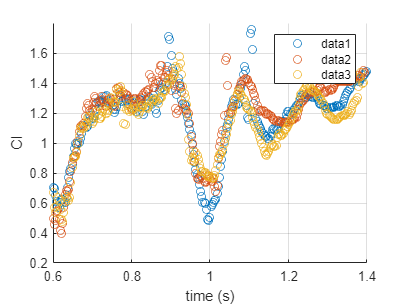


clf
hold on
A = 0.15*0.8;
for i = enumerate(file_names)
    d = data.("a"+file_names(i));
    d = d(d.t>0.6, :);
    d = d(d.t<1.4, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    scatter(d.t, Cl);
end
hold off
legend
xlabel("time (s)")
ylabel("Cl")
grid("on")

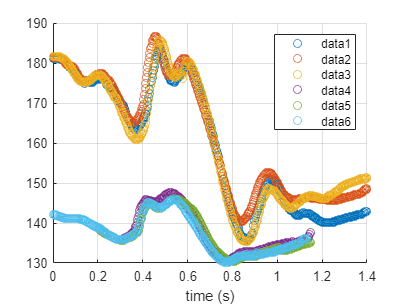

file_names = [...
    "1_dynamic_dihedral_s1",...
    "2_dynamic_dihedral_s1",...
    "3_dynamic_dihedral_s1",...
    "1_fixed_dihedral_s2",...
    "2_fixed_dihedral_s2",...
    "4_fixed_dihedral_s2",...
    ];

clf
hold on
A = 0.15*0.8;
for i = file_names
    d = data.("a"+i);
    d.left_rel_z = data.("a"+i).leftz - data.("a"+i).midz;
    d.left_rel_y = data.("a"+i).lefty - data.("a"+i).midy;
    d.left_rel_x = data.("a"+i).leftx - data.("a"+i).midx;
    d.right_rel_z = data.("a"+i).rightz - data.("a"+i).midz;
    d.right_rel_y = data.("a"+i).righty - data.("a"+i).midy;
    d.right_rel_x = data.("a"+i).rightx - data.("a"+i).midx;
        
    data.("a"+i).angles = 180 - atand(d.right_rel_z./d.right_rel_x) + atand(d.left_rel_z./d.left_rel_x);
    scatter(d.t, data.("a"+i).angles);
end
hold off
legend
xlabel("time (s)")
grid("on")

% clf
% storedrag = [];
% storelift = [];
% storeaoa = [];
% storepitch = [];
% hold on
% 
% for i = enumerate(file_names)
%     yyaxis left
%     d = data.("a"+file_names(i));
%     d = d(d.t<1.4, :);
%     plot(d.t, mean(-d.drag,2), 'DisplayName',"drag");
%     plot(d.t, mean(d.lift,2), 'DisplayName',"lift");
%     ylabel("Force (N)")
%     yyaxis right
%     ylabel("Angle (degrees)")
%     plot(d.t, mean(-(d.angles-180)/2,2), 'DisplayName',"average dihedral angle");
%     plot(d.t, mean(d.pitch,2), 'DisplayName',"pitch");
% 
% end
% hold off
% legend('Location', "southeast")
% xlabel("Time (s)")
% xlim([0.5,1.4])
% grid("on")

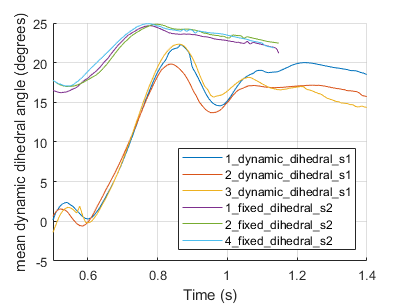

clf
storedrag = [];
storelift = [];
storeaoa = [];
storepitch = [];
hold on

for i = enumerate(file_names)
    d = data.("a"+file_names(i));
    plot(d.t, mean(-(d.angles-180)/2,2), 'DisplayName',file_names(i));

end
hold off
legend('Location', "southeast")
xlabel("Time (s)")
xlim([0.5,1.4])
grid("on")
leg = legend();
set(leg,'Interpreter', 'none', 'Location', 'SouthEast');
ylabel("mean dynamic dihedral angle (degrees)")
f = gcf;
exportgraphics(f,'figures/dynamic_dihedral_angle.png','Resolution',300) 

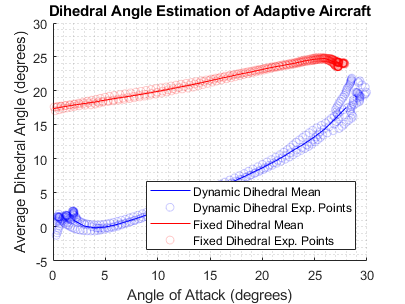


clf
A = 0.15*0.8;
min_r = 0;
max_r = 40;
storeang = [];
storeaoa = [];
hold("on")
enumerate = @(values) [1:length(values)];
for i = enumerate(file_names(1:3))
    d = data.("a"+file_names(i));
    d = d(d.t>0.5, :);
    d = d(d.t<0.84, :);
    angles = interp1(d.AoA, -(d.angles-180)/2, min_r:max_r);
    storeang(:, i) = angles;
    storeaoa(:, i) = min_r:max_r;
    scatter(d.AoA, -(d.angles-180)/2, "blue","MarkerEdgeAlpha",0.2, 'HandleVisibility',"off");
end

plot(min_r:max_r, mean(storeang,2), "blue")
%dummy scatter for legend
scatter(d.AoA-100, d.angles-100, "blue","MarkerEdgeAlpha",0.2);


storeang = [];
storeaoa = [];

for i = enumerate(file_names(4:6))
    i = i + 3;
    d = data.("a"+file_names(i));
    d = d(d.t>0.5, :);
    d = d(d.t<0.9, :);
    angles = interp1(d.AoA, -(d.angles-180)/2, min_r:max_r);
    storeang(:, i - 3) = angles;
    storeaoa(:, i - 3) = min_r:max_r;
    scatter(d.AoA, -(d.angles-180)/2, "red","MarkerEdgeAlpha",0.2, 'HandleVisibility',"off");
end

plot(min_r:max_r, mean(storeang,2), "red")
%dummy scatter for legend
scatter(d.AoA-100, d.angles, "red","MarkerEdgeAlpha",0.2);

% high =  max(storecl,[],2);
% low = min(storecl,[],2);
% x = (min_r:max_r)';
% patchx = [x; x(end:-1:1)];
% patchy = [low; high(end:-1:1)];
% P1 = patch(patchx, patchy, 'r');
% set(P1, 'facecolor', "cyan", 'edgecolor', 'none');
% set(P1, 'facealpha', 0.1);
% 
% high =  mean(storecl,2) + std(storecl,[],2);
% low = mean(storecl,2) - std(storecl,[],2);
% x = (min_r:max_r)';
% patchx = [x; x(end:-1:1)];
% patchy = [low; high(end:-1:1)];
% P2 = patch(patchx, patchy, 'r');
% set(P2, 'facecolor', "yellow", 'edgecolor', 'none');
% set(P2, 'facealpha', 0.2);

hold("off")
xlabel("Angle of Attack (degrees)")
ylabel("Average Dihedral Angle (degrees)")
grid("on")
xlim([0,30])
ylim([-5,30])
legend("Dynamic Dihedral Mean", "Dynamic Dihedral Exp. Points", "Fixed Dihedral Mean", "Fixed Dihedral Exp. Points", "Location","southeast")
title("Dihedral Angle Estimation of Adaptive Aircraft")

grid
set(gca,'gridlinestyle','-')
grid minor

exportgraphics(gcf,'figures/dihedral_angle.png') 

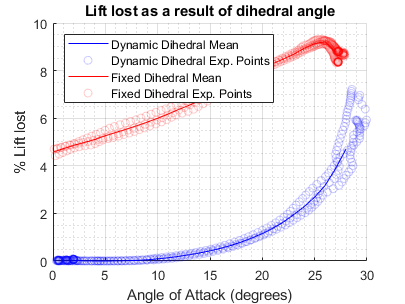

file_names = [...
    "1_dynamic_dihedral_s1",...
    "2_dynamic_dihedral_s1",...
    "3_dynamic_dihedral_s1",...
    "1_fixed_dihedral_s2",...
    "2_fixed_dihedral_s2",...
    "4_fixed_dihedral_s2",...
    ];

clf
A = 0.15*0.8;
min_r = 0;
max_r = 30;
storeang = [];
storeaoa = [];
hold("on")
enumerate = @(values) [1:length(values)];
for i = enumerate(file_names(1:3))
    d = data.("a"+file_names(i));
    d = d(d.t>0.5, :);
    d = d(d.t<0.84, :);
    angles = interp1(d.AoA, (1 - cosd(-(d.angles-180)/2))*100, min_r:max_r);
    storeang(:, i) = angles;
    storeaoa(:, i) = min_r:max_r;
    scatter(d.AoA, (1 - cosd(-(d.angles-180)/2))*100, "blue","MarkerEdgeAlpha",0.2, 'HandleVisibility',"off");
end

plot(min_r:max_r, mean(storeang,2), "blue")
%dummy scatter for legend
scatter(d.AoA-100, d.angles-100, "blue","MarkerEdgeAlpha",0.2);


storeang = [];
storeaoa = [];

for i = enumerate(file_names(4:6))
    i = i + 3;
    d = data.("a"+file_names(i));
    d = d(d.t>0.5, :);
    d = d(d.t<0.9, :);
    angles = interp1(d.AoA, (1 - cosd(-(d.angles-180)/2))*100, min_r:max_r);
    storeang(:, i - 3) = angles;
    storeaoa(:, i - 3) = min_r:max_r;
    scatter(d.AoA, (1 - cosd(-(d.angles-180)/2))*100, "red","MarkerEdgeAlpha",0.2, 'HandleVisibility',"off");
end

plot(min_r:max_r, mean(storeang,2), "red")
%dummy scatter for legend
scatter(d.AoA-100, d.angles, "red","MarkerEdgeAlpha",0.2);


hold("off")
xlabel("Angle of Attack (degrees)")
ylabel("% Lift lost")
xlim([min_r,max_r])
legend("Dynamic Dihedral Mean", "Dynamic Dihedral Exp. Points", "Fixed Dihedral Mean", "Fixed Dihedral Exp. Points", "Location","northwest")
title("Lift lost as a result of dihedral angle")

grid
set(gca,'gridlinestyle','-')
grid minor

exportgraphics(gcf,'figures/dihedral_list_lost.png') 

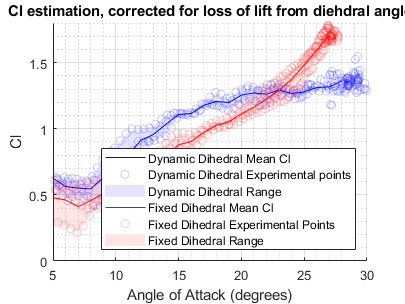

file_names = [...
    "1_dynamic_dihedral_s1",...
    "2_dynamic_dihedral_s1",...
    "3_dynamic_dihedral_s1",...
    "1_fixed_dihedral_s2",...
    "2_fixed_dihedral_s2",...
    "4_fixed_dihedral_s2",...
    "2_cf_wing",...
    "3_cf_wing"
    ];

clf
A = 0.15*0.8;
min_r = 0;
max_r = 30;
storecl = [];
storeaoa = [];
hold("on")
enumerate = @(values) [1:length(values)];
for i = enumerate(file_names(1:3))
    d = data.("a"+file_names(i));
    d = d(d.t>0.55, :);
    d = d(d.t<0.85, :);
    Cl = (2 .* (d.lift ./ cosd(-(d.angles-180)/2))) ./ (1.225 .* d.v.^2 .*A);
    ClInterp = interp1(d.AoA, Cl, min_r:max_r);
    storecl(:, i) = ClInterp;
    storeaoa(:, i) = min_r:max_r;
    scatter(d.AoA, Cl, "blue","MarkerEdgeAlpha",0.2, 'HandleVisibility',"off");
end

plot(min_r:max_r, mean(storecl,2), "blue")
%dummy scatter for legend
scatter(d.AoA-100, Cl-100, "blue","MarkerEdgeAlpha",0.2);

high =  max(storecl,[],2);
low = min(storecl,[],2);
x = (min_r:max_r)';
high = high(5:30);
low = low(5:30);
x = x(5:30);
patchx = [x; x(end:-1:1)];
patchy = [low; high(end:-1:1)];
P1 = patch(patchx, patchy, 'r');
set(P1, 'facecolor', "blue", 'edgecolor', 'none');
set(P1, 'facealpha', 0.1);


storecl = [];
storeaoa = [];

for i = enumerate(file_names(4:6))
    i = i + 3;
    d = data.("a"+file_names(i));
    d = d(d.t>0.45, :);
    d = d(d.t<0.86, :);
    Cl = (2 .* (d.lift) ./ cosd(-(d.angles-180)/2)) ./ (1.225 .* d.v.^2 .*A);
    ClInterp = interp1(d.AoA, Cl, min_r:max_r);
    storecl(:, i - 3) = ClInterp;
    storeaoa(:, i - 3) = min_r:max_r;
    scatter(d.AoA, Cl, "red","MarkerEdgeAlpha",0.2, 'HandleVisibility',"off");
end

plot(min_r:max_r, mean(storecl,2), "red")
%dummy scatter for legend
scatter(d.AoA-100, Cl-100, "red","MarkerEdgeAlpha",0.2);


high =  max(storecl,[],2);
low = min(storecl,[],2);
x = (min_r:max_r)';
high = high(5:27);
low = low(5:27);
x = x(5:27);
patchx = [x; x(end:-1:1)];
patchy = [low; high(end:-1:1)];
P1 = patch(patchx, patchy, 'r');
set(P1, 'facecolor', "red", 'edgecolor', 'none');
set(P1, 'facealpha', 0.1);



hold("off")
xlabel("Angle of Attack (degrees)")
ylabel("Cl")
xlim([5,max_r])
ylim([0,1.8])
legend("Dynamic Dihedral Mean Cl", "Dynamic Dihedral Experimental points", "Dynamic Dihedral Range", ...
    "Fixed Dihedral Mean Cl", "Fixed Dihedral Experimental Points", "Fixed Dihedral Range", ...
    "Location","southeast")
title("Cl estimation, corrected for loss of lift from diehdral angle")

grid
set(gca,'gridlinestyle','-')
grid minor


exportgraphics(gcf,'figures/cl_estimation_comparison_corrected.png')


clf
set(gcf, 'position', [680   558   560   420])

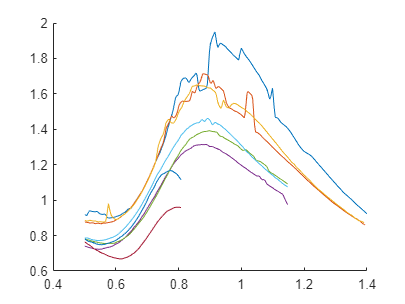

file_names = [...
    "1_dynamic_dihedral_s1",...
    "2_dynamic_dihedral_s1",...
    "3_dynamic_dihedral_s1",...
    "1_fixed_dihedral_s2",...
    "2_fixed_dihedral_s2",...
    "4_fixed_dihedral_s2",...
    "2_cf_wing",...
    "3_cf_wing"
    ];
clf
hold on
save_error = [];
for i = file_names
    d = data.("a"+i);
    d = d(d.t>0.5, :);
    d = d(d.t<1.4, :);
    plot(d.t, d.pitch_error, 'DisplayName', i)
    save_error = [save_error d.pitch_error'];
end

hold off

mean(save_error, 'omitnan')

ans = 1.1552

std(save_error, 'omitnan')

ans = 0.2932

length(save_error)

ans = 1754

file_names = [...
    "1_dynamic_dihedral_s1",...
    "2_dynamic_dihedral_s1",...
    "3_dynamic_dihedral_s1",...
    "1_fixed_dihedral_s2",...
    "2_fixed_dihedral_s2",...
    "4_fixed_dihedral_s2",...
    "2_cf_wing",...
    "3_cf_wing"
    ];
clf
hold on
save_error = [];
for i = file_names
    d = data.("a"+i);
    d = d(d.t>0.5, :);
    d = d(d.t<1.4, :);
    plot(d.t, d.glide_angle_error, 'DisplayName', i)
    save_error = [save_error abs(d.glide_angle_error)'];
end
mean(save_error, 'omitnan')

ans = 4.2848

std(save_error, 'omitnan')

ans = 4.0910

length(rmmissing(save_error))

ans = 1749

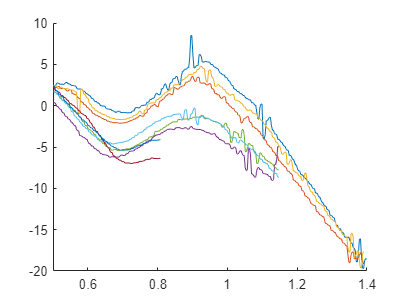

xlim([0.5,1.4])
hold off